# Interactive manuscript

Welcome to this MATLAB Live Script which brings to life the figures in Walker et al. (2020) and enables you to interact with the wealth of data published with this article - 216 sperm flagellar waveforms are at your fingertips! 

**Reference**: Walker BJ, Phuyal S, Ishimoto K, Tung C-K, Gaffney EA. (2020) Computer-assisted beat-pattern analysis and the flagellar waveforms of bovine spermatozoa. *R. Soc. Open Sci*. **7**: 200769

**User instructions**: You must run this script from the parent folder, i.e. the main directory where you have downloaded our GitHub repository. In other words, your Current Folder in MATLAB must be set to '...\CambridgeFertiliTEAM_DataChallenge2_SolutionTitle'. 

% NOTE: This MATLAB live script contains a mixture of code written by
% -- the authors of Walker BJ, Phuyal S, Ishimoto K, Tung C-K, Gaffney EA. 
% (2020) Computer-assisted beat-pattern analysis and the flagellar waveforms 
% of bovine spermatozoa. R. Soc. Open Sci. 7: 200769
% (particularly for reproducing Fig. 1)
% -- the members of Cambridge InfertiliTEAM for inFer GW4 network Hackathon
clear; clc; close all; 

## Large-scale quantification of flagellar beating

Let's start by reproducing and exploring Fig. 1. Click 'Get started' below to load the data and functions necessary for other sections to run.

 

% add folders to path so can e.g. run functions in those folders
addpath('Data',  'Functions',  'Images',  'Movies')

% load data for 
% This function call is a bit slow; don't run unless necessary
if ~exist('data', 'var') % check if data exists 
    data = load_all_data();
end

load('Data/pop_pca.mat','modes','coeff','A_mask','B_mask')

% load data for figure with real beat; assign beat data to new variable to
% avoid variable name conflict
load('Data/real.mat','beat')
realBeat = beat;

% load data for figure with synthetic beat; assign beat data to new variable
load('Data/synthetic.mat','beat')
syntheticBeat = beat;

% colours for real and synthetic beat figures
cc = importdata('Data/colormap.txt');
inds = 1 : 4 : 100;
cc = cc(inds,:);

% find min and max of all y values in waveform, for purpose of ylim for
% plots
allValues = [];
for i=1:216
    allValues = [allValues; data{i}.cartesian(:,:,2)];
end
waveformMiny = min(allValues,[],"all");
waveformMaxy = max(allValues,[],"all");

### Image of swimming bovine spermatozoa - Fig. 1(a)

Here is a sample captured frame from a video of a fresh spermatozoon swimming in Tyrode Albumin Lactate Pyruvate (TALP), a standard medium for bovine sperm.

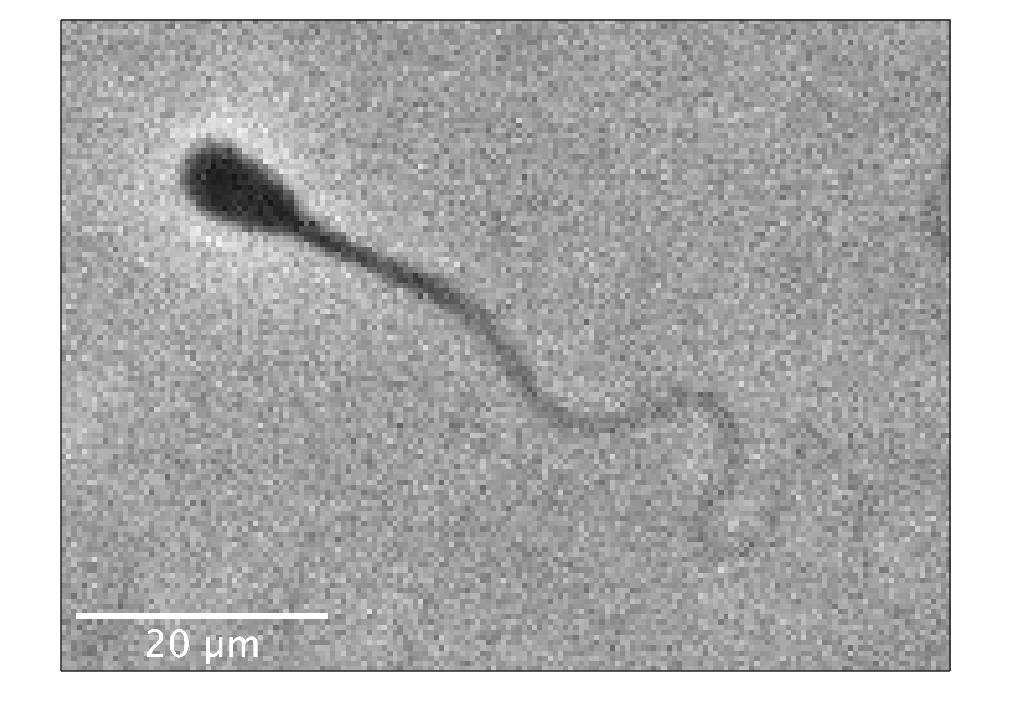

 
figure
imshow( imread('Data/raw.tif') ,[0 255]);
axis on
set(gca,'XTick',[],'YTick',[])
box on

### Automated tracing of the flagellum - Fig. 1(b)

The next step is to trace the flagellum. Walker et al. (2020) use an automated methodology developed in one of their previous studies. Click 'View' to see the traced flagellum for to the sample frame shown above.

**Reference**: Walker BJ, Ishimoto K, Wheeler RJ. 2019 Automated identification of flagella from videomicroscopy via the medial axis transform. Sci. Rep. 9, 5015. (doi:10.1038/s41598-019-41459-9).

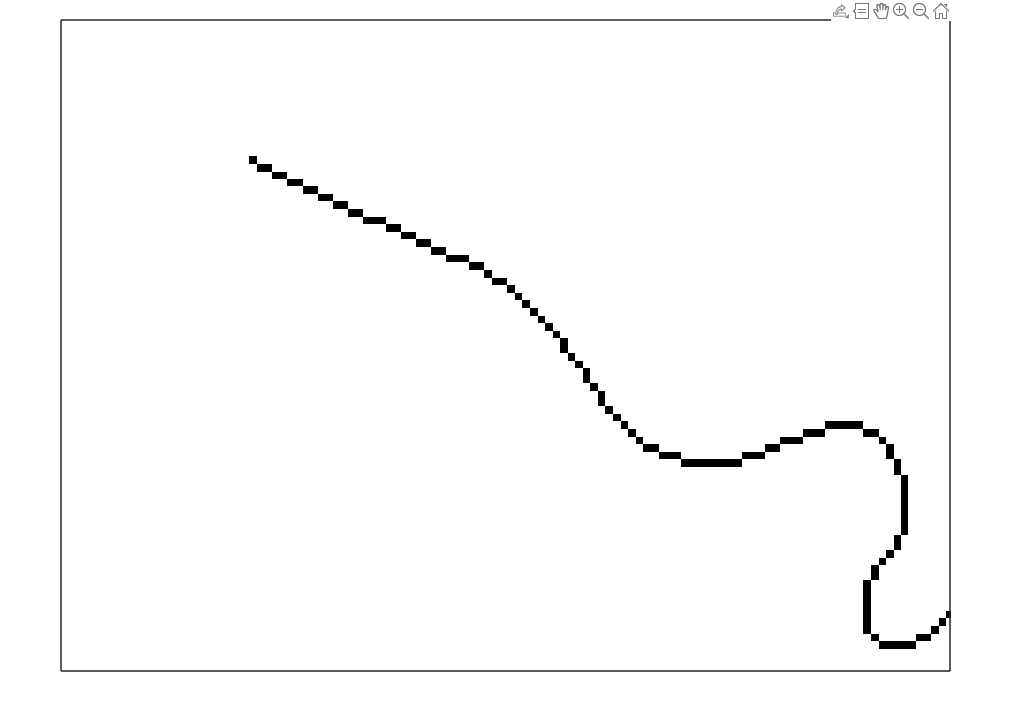

 
figure
imshow( imread('Data/flag.tif') ,[0 255]);
axis on
set(gca,'XTick',[],'YTick',[])
box on

### Animated real flagellar waveform - Fig. 1(c)

By tracing the flagellum in each video frame, it is possible to reconstruct the waveform over an entire beating period. 

**Click 'Watch' below to make Fig. 1(c) come to life!** The captured waveform (thick black line) is shown against an envelope of light grey lines depicting the waveform at all timepoints within a beating period.

*Note: There will be some waiting time while MATLAB plots the figure for the first time, after which you can click the Play button underneath the animation to watch the beating waveform in real time. *

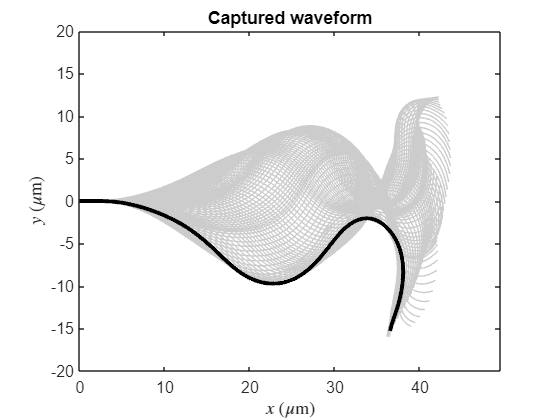

 

figure
for timepoint=1:100
    clf
    % plot in grey the waveform at all timepoints
    plot(realBeat.xy(:,:,1)',realBeat.xy(:,:,2)','color','#cccccc')
    hold on
    % plot the waveform at the current timepoint
    plot(realBeat.xy(timepoint,:,1)',realBeat.xy(timepoint,:,2)','color','k','LineWidth',3)
    axis equal
    xlabel('$x$ ($\mu$m)','interpreter','latex')
    ylabel('$y$ ($\mu$m)','interpreter','latex')
    set(gca,'FontSize',12)
    xlims = [0,49.457];
    ylims = [-20,20];
    xlim(xlims)
    ylim(ylims)
    set(gca,'XTick',[0 10 20 30 40])
    title('Captured waveform')
    drawnow
end

### Beyond the manuscript

You can explore the dataset provided by Walker et al. (2020) in more detail with our Live Script **explore_waveforms.mlx**. Aditional features of this live script:

- watch the beating waveform of all 216 sperm 

- compare the waveforms of two sperm side by side

### Animated synthetic flagellar waveform - Fig. 1(d)

An exciting application of the data provided by Walker et al. (2020) is the possibility to generate synthetic flagellar waveforms. These are new computer-generated waveforms that have not been directly observed with video microscopy, but are consistent with their dataset of over 200 sperm bovine waveforms. The similarity is based on a quantitative analysis using the method of principal component analysis (PCA), which will be described in more detail below.

**Click 'Watch' below to make Fig. 1(d) come to life!** The synthesised waveform (thick black line) is shown against an envelope of light grey lines depicting the waveform at all timepoints within a beating period.

*Note: There will be some waiting time while MATLAB plots the figure for the first time, after which you can click the Play button underneath the animation to watch the beating waveform in real time. *


 

figure
for timepoint=1:100
    clf
    % plot in grey the waveform at all timepoints
    plot(syntheticBeat.xy(:,:,1)',syntheticBeat.xy(:,:,2)','color','#cccccc')
    hold on
    % plot the current waveform
    plot(syntheticBeat.xy(timepoint,:,1)',syntheticBeat.xy(timepoint,:,2)','color','k','LineWidth',3)
    axis equal
    xlabel('$x$ ($\mu$m)','interpreter','latex')
    ylabel('$y$ ($\mu$m)','interpreter','latex')
    set(gca,'FontSize',12)
    xlims = [0,49.457];
    ylims = [-20,20];
    xlim(xlims)
    ylim(ylims)
    set(gca,'XTick',[0 10 20 30 40])
    title('Synthetic waveform')
    drawnow
end

### Beyond the manuscript

You can explore the dataset provided by Walker et al. (2020) in more detail with our Live Script **explore_waveforms.mlx**. Aditional features of this live script:

- generate and watch a brand new synthetic waveform - there is no limit to what a (synthetic) sperm can do! 